Checkpoint 5.1

Range 0:

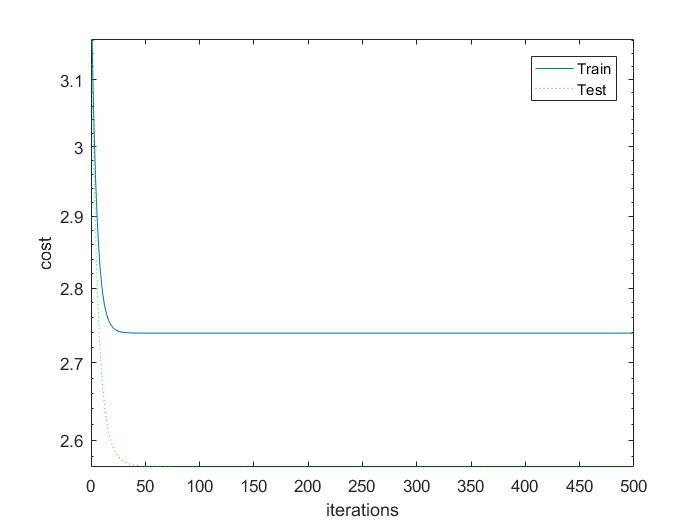

What we can see here is that when the weights are initiallized to 0 the net is learning slow and then stops at one value, which would be the local minima. When we look at the final weights we can see that none of the weights have actually changed but the weight for bias for the output layer. When we look at the equation 8 we can see that it actually makes sense and mathematically none of the weights but the output bias weight should change. It means that the network learnt the bias (which in fact is the mean value of the output) and will not be learning anymore.

It is worth noting here that the test data has smaller error than the train data. The explanation for that is that the model as we previously showed is learning only the mean value. So if the train data had huge variance and test data had small variance it would be possible that it happens.

Range 0.5:

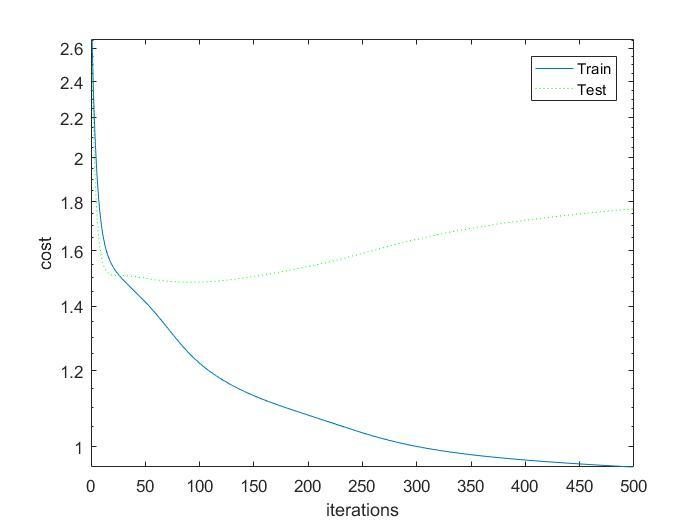

Range 10000:

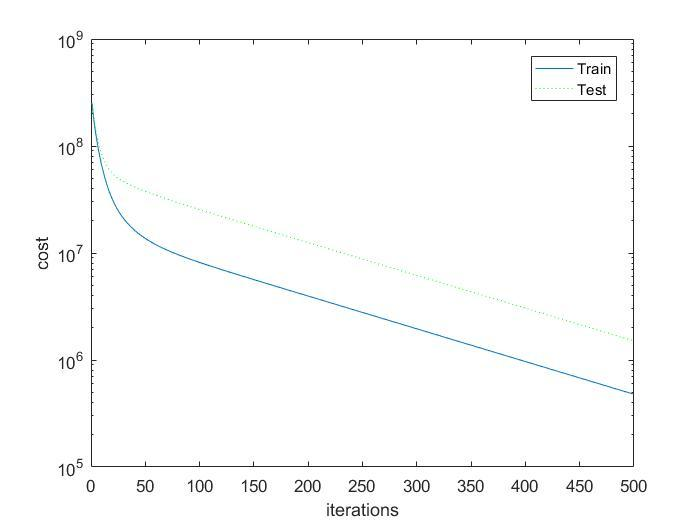

We can see that having large initial weights results in a large initial error of the network this is due to the fact that the output from the network (2nd weights layer) will be large and will be far away from the target value. We can see that the error is decaying but relativly slow this is due to the fact that tanh function is basically a step function for big initial weight. If we look at the following equation 9 we can see that *z will be *either 1 or -1 meaning that the whole sum in equation 9 is reduced to 0 if we dont use weight decay (alpha is 0). Having a weight decay can speed up the process of learning for large weights. The other layer will be learning but it's not enough as we need both of the layers to work properly:

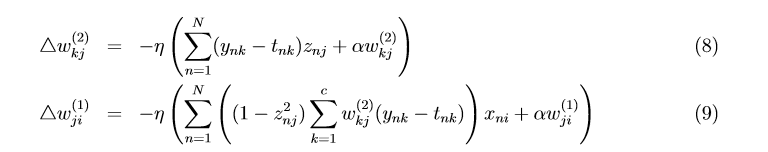

Checkpoint 5.2

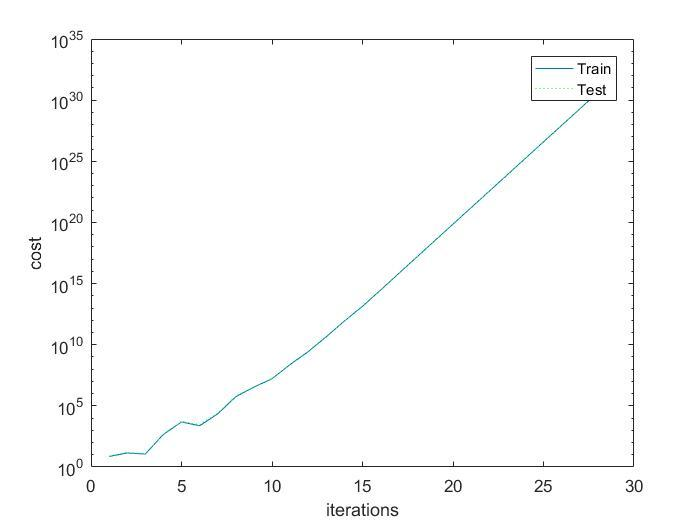

Here we can see a learning rate of 0.02, which results in an unstable model as the jumps between iterations are too large and it never converges.

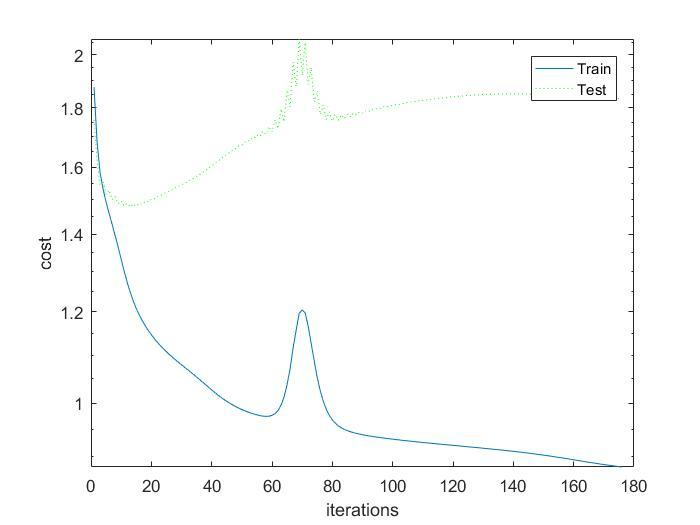

This plot shows the learning with learning rate of 0.007. We can see that it is quickly reducing the cost value but additionally we can see an overshoot at one point.

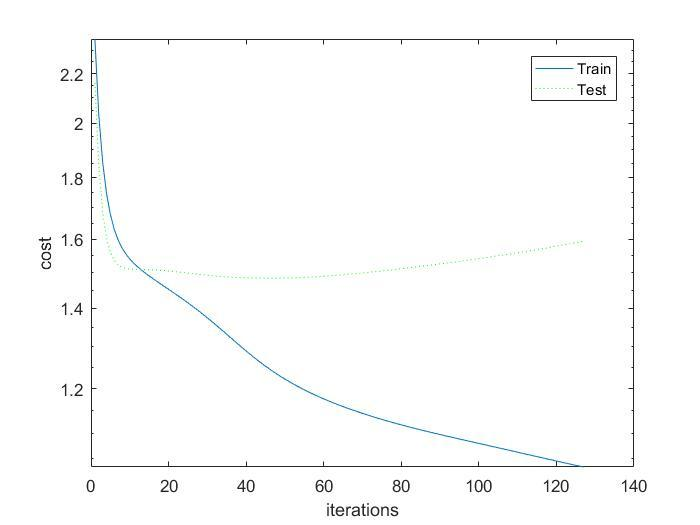

This plot shows learning with 0.002. It seems to have acceptable results as it's not overshooting at any point and we learn very quickly. Basically after 10-20 iterations the test error is not dropping anymore.

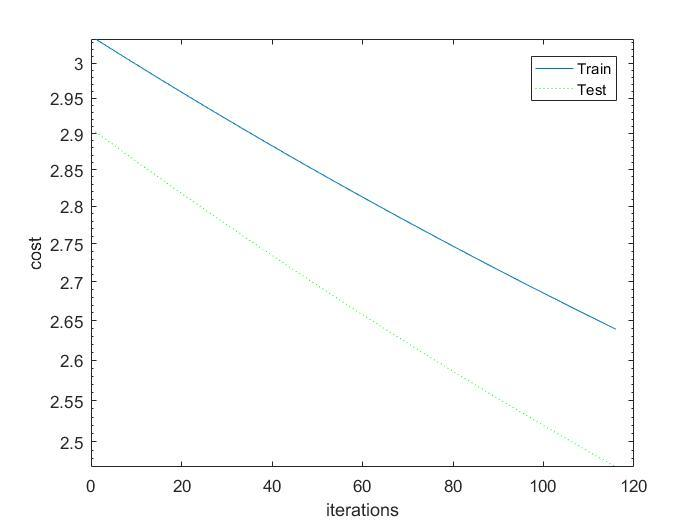

This example shows the learning plot for the very small learning rate of 0.00001. You can see that the network learns very slowly in that case.

Additionally we tried playing with the learning rate in exercise 5b.

Below learning rate 0.005

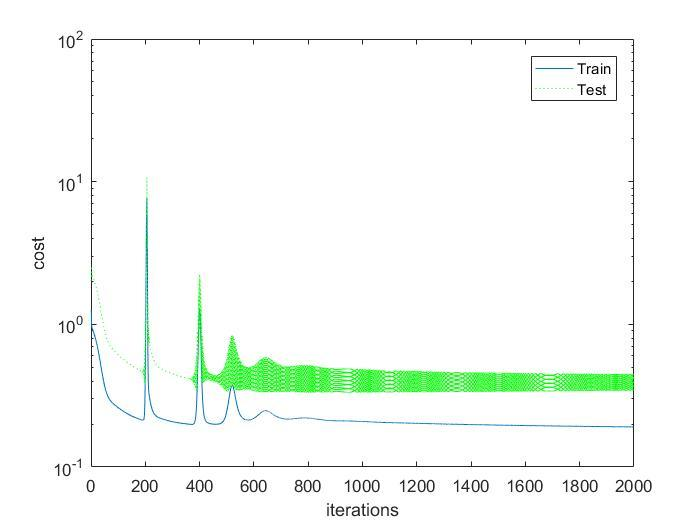

Below learning rate 0.003

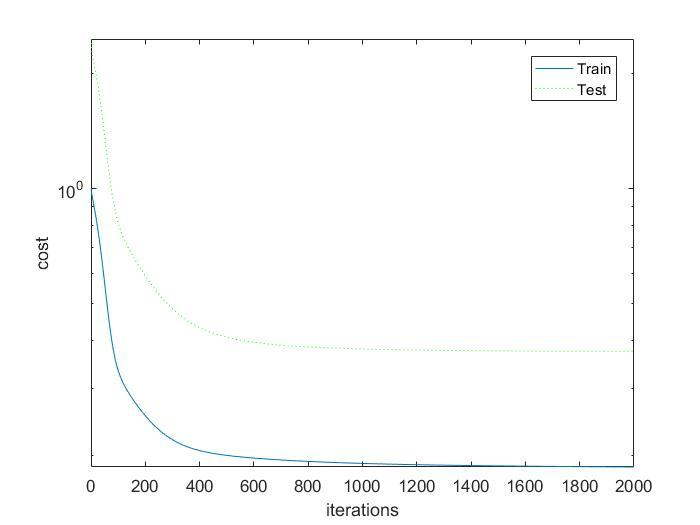

Checkpoint 5.3

In this exercise we looked at plots of the gradient norm and  train cost difference.

Train const difference is the difference between cost function in current iteration and cost function in the previous iteration. Additionally as the model learns it should be dropping ebcause aas we get closer to the minimum it should be learning slower.

Gradient norm is a norm (in this case euclidan length) of the gradient. We expect it to go to zero as the model learns. This is because the point in which all gradients will be zero is a local/global minimum.

We can set a threshold on these values to determine when to stop learning - the stop-criterion. It would be additionally nice to add an condition that the stop cirterion is only valid if in the n preceeding samples the value didn't vary too much. It is done to avoid cases where the signal is still not stable (for instance due to too large learning rate as in the example).

The oscillation is caused by the solution oscillating around minimum point. As the model was trained on the training data it will be smaller for the training set than for the test set. But the oscillations can be observerd on the both plots.